clc;
close all;
clearvars;
% Lead Compensator Design
plant_num = [4];
plant_den = [1 2];
plant_tf = tf(plant_num,plant_den);
comp_num = [0.36 1];
comp_den = [0.09 1];
comp_tf = tf(comp_num,comp_den);
% Plotting Gain and Phase margin for plant
figure;
margin(plant_tf);
grid on;
hold on;
% Compensated System
lead_comp_sys = plant_tf*comp_tf;
disp(lead_comp_sys);

  tf with properties:

       Numerator: {[0 1.4400 4]}
     Denominator: {[0.0900 1.1800 2]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



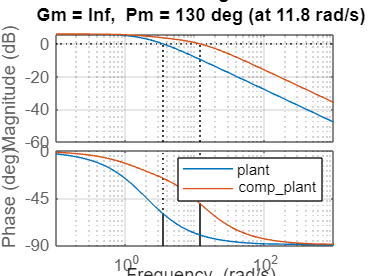

margin(lead_comp_sys);
hold off;
legend ('plant', 'comp_plant');

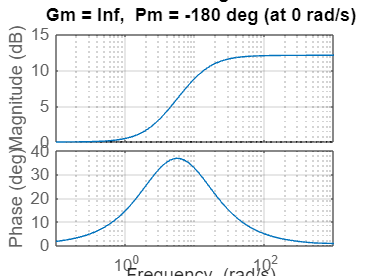

% Plotting Gain and Phase margin for compensator
figure;
margin(comp_tf);
grid on;